#                Antenna Array Processing

##                                            HW4

                 Mohammadreza Arani         :::::::::::::         810100511

                                                            1401/08/              

clear; clc; close all;

## Q1:

Initializations and the problem definition:

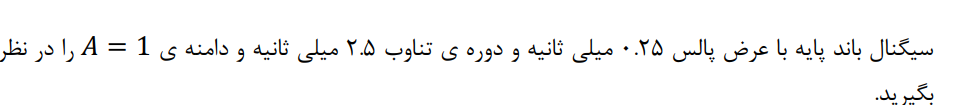

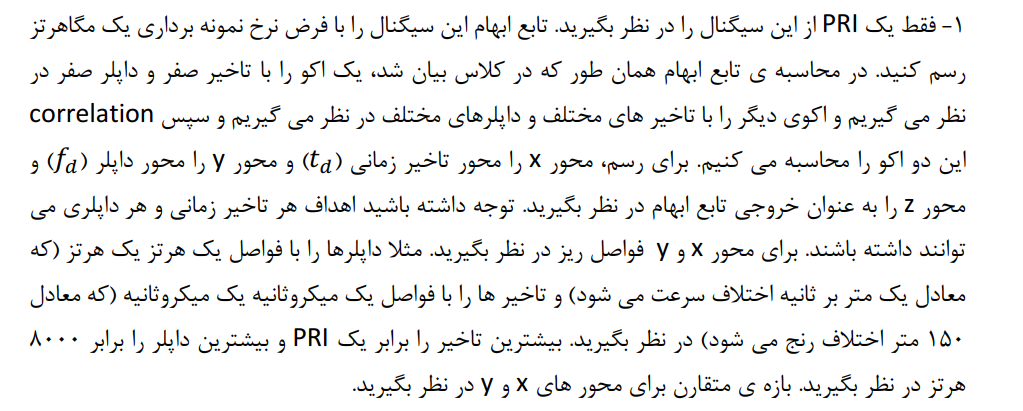

### Initialization:

% Signals are considered to be in Low Frequency Band
ts =  1e-5; % --> to get 1 MHz --> 
fs=1/ts; % sampling rate --> 100Hz
C=300e6; % light speed

Tau_length = 0.25e-3;  % 0.25ms

tau_num=Tau_length/ts;  % --> Consider a single sample on the signal
tau=tau_num*ts; % --> the signal length would be equal to number of samples multiplied by length of each sample!

PRI=2.5e-3; % 2.5 ms
PRI_num=round(PRI/ts); % --> number of sqaured pulses in signal

PRF=1/PRI;

A=1;


Trecording=1 * PRI;   % --> Recording time at the receiver!

deltaf=1/Trecording; % Frequency Resolution

pulse_num=round(Trecording/PRI); % Number of pulse in recording time
sample_num=round(Trecording/ts);

t=0:ts:Trecording-ts; % Time Vector 
freq=-fs/2:deltaf:fs/2-deltaf; % Frequency Vector

% Create Our Signal : The one Pulse:
SL_PRI=A* [ones(1,tau_num) zeros(1,PRI_num-tau_num)]; % single pulse in the interval of sending and receiving
sl=repmat(SL_PRI,1,pulse_num); % Repeated pulse for each PRI in Trecording


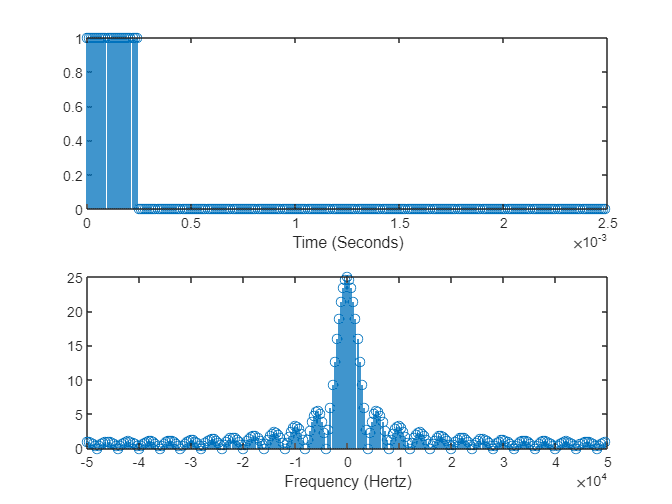


figure(1)
subplot(2,1,1)
stem(t,sl) % The Signal itself --> Pulse Train
xlabel('Time (Seconds)')
subplot(2,1,2)
slf=fftshift(fft(sl)); % shifted fft signal --> Fourier transformation --> I expect to see the sampled form of the expected Fourier transform with the distance of 1/PRI = PRF
stem(freq,abs(slf)) % Frequency Domain
xlabel('Frequency (Hertz)')

### Abmibuity Function:

Ambiguity function as defined previously in lecture 11, is represented below:

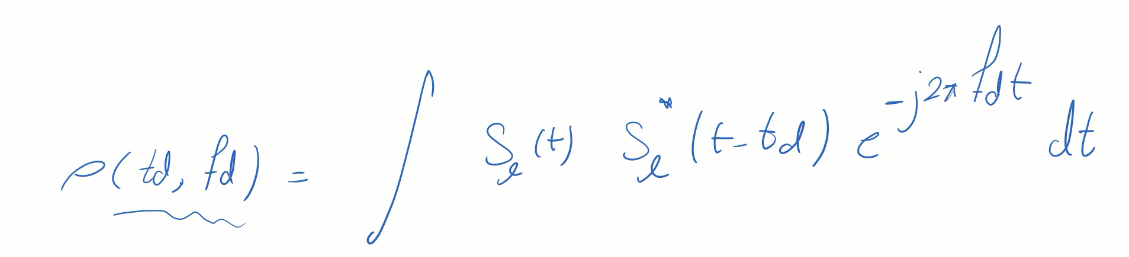

This can be implemented using:

    1- Correlation of 2 signals

    2- Multiplication of Fourier Transforms 

Also, in matlab we can either use symbolic function to plot the result or we can use Meshgrid to produce a surface based on fd, td!

% define td and fd vectors as mentioned in the first question:
delay_vector = -PRI : 1e-5 : PRI ;
doppler_freq_vector = -4e3: 1 : 4e3 ; % 8000Hz with 1Hz resolution

P = zeros(length(doppler_freq_vector),length(delay_vector));

for i=1:length(delay_vector)
    for j=1:length(doppler_freq_vector)
        td = delay_vector(i) ;
        fd = doppler_freq_vector(j);
        P(j,i) = sum(sl.*conj(circshift(sl,round(td/ts))) .* exp(-1j*2*pi*fd.*t)) ;  % sl(t)*sl(t-td)^ * exp(-1j*2*pi*fd*t) --> summation on t


    end
end

% p(fd,td) = int(sl.*conj(circshift(sl,round(td/ts) )).*exp(-1j*2*pi*fd*t)
% , t ); --> Symbolic Expression

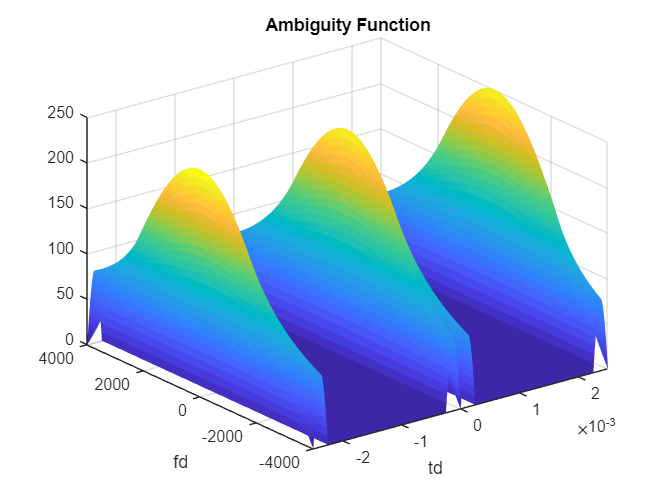


[TD,FD] = meshgrid(delay_vector , doppler_freq_vector) ; % Baze o motegharen greftam... Nemidunestam manzur ghesmate manfias ya mosbataro ham nesfe konam

figure()
h=surf(TD,FD,abs(P));
xlabel("td")
ylabel("fd")
title("Ambiguity Function")
set(h,'LineStyle','none')

### Q2:

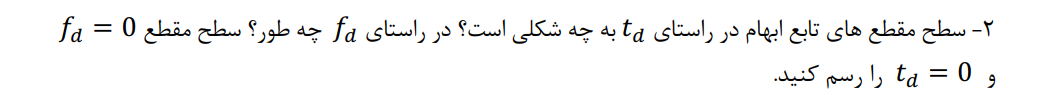

we can view the fd=0 plane below:

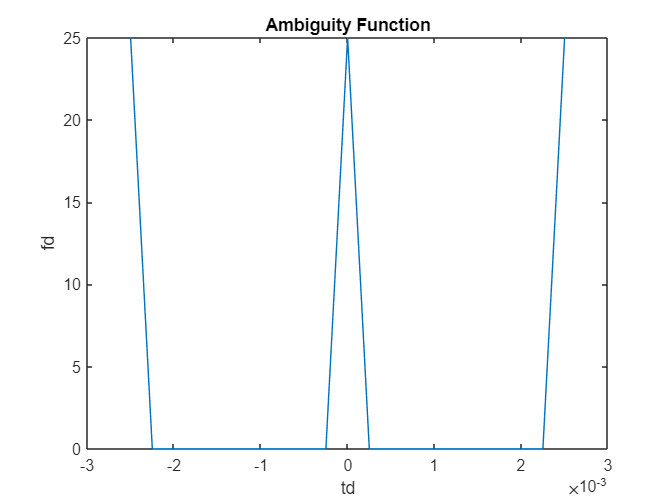

figure()
mid = floor(length(doppler_freq_vector)/2)+1; % the middle point
plot(delay_vector,abs( P(mid,:) ));
xlabel("td")
ylabel("fd")
title("Ambiguity Function") 

Sounds like triangles! --> Perfect shape is Delta Form --> COnvolution of 2 rectangular pulse is triangle

And for the td = 0 plane we have:

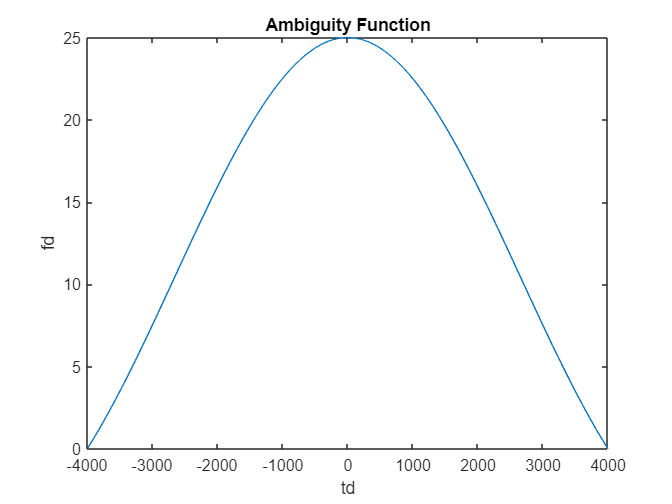

figure()
mid_t = floor(length(delay_vector)/2)+1; % the middle point
plot(doppler_freq_vector,abs( P(:,mid_t) ));
xlabel("td")
ylabel("fd")
title("Ambiguity Function") 

Looks like a sink function --> Fourier Transform of  a rectangular Pulse for td --> 0 

### Q3:

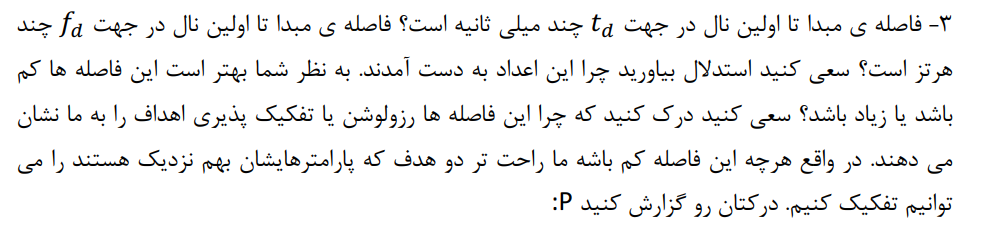

we have already mentioned previously, that the first Null in td axis is:

for fd=0:

$p\left(\textrm{td},\textrm{fd}\right)=\int s_l \left(t\right)s_l {\left(t-\textrm{td}\right)}^* \;e^{-1\textrm{j2}\pi \;\textrm{fd}\;t} \textrm{dt}-\to \;$fro fd =0 : 

$p\left(t_d ,0\right)=\int \;s_l \left(t\right)s_l \left(t-\textrm{td}\right)\textrm{dt}$ --> Convolution of 2 rectangular pulses:

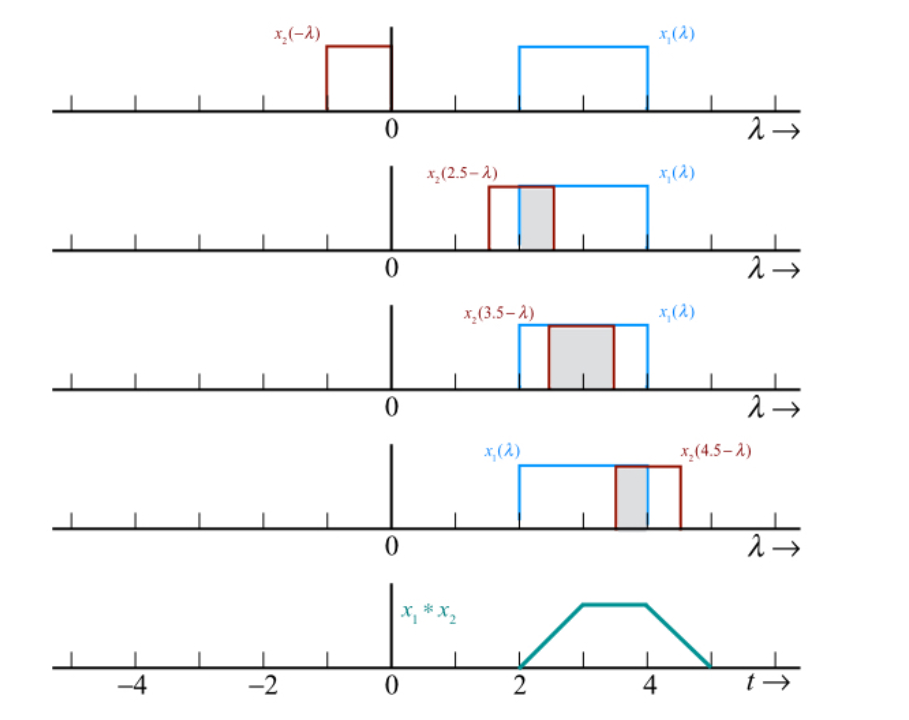

First Null happens when the other sliding pulse has fully passed through the fixed rectangular pulse --> meaning in 2*$\tau$!

Same happens for the fd axis -->

td =0:

$p\left(0,f_d \right)=\int s_l \left(t\right)s_l {\left(t\right)}^* \;e^{-1\textrm{j2}\pi \;\textrm{fd}\;t} \textrm{dt}$ --> $p\left(0,\textrm{fd}\right)=\int \;\;{\left|{\;s}_l \left(t\right)\right|}^2 \;e^{-1\textrm{j2}\pi \;\textrm{fd}\;t} \textrm{dt}$ --> $F\left\lbrace s_l \right\rbrace -\to \textrm{Sinc}\left(f\right)$  :::::::

                                                                                                                $F\left\lbrace {\left|s_l \right|}^2 \right\rbrace -\to \textrm{Sinc}*\textrm{Sinc}$   ::::: Still a Sinc function because the other side remains still a rectangular pulse!!!!!! --> the first Null in the sinc function happens at $\frac{1}{\tau }$ as mentioned in the class!  --> $\frac{1}{\tau }=\frac{1}{0\ldotp 25\textrm{ms}}=4000\;\textrm{Hz}$ --> which is the exact point we see in the figure above!

These 2 factors are in harmony and there exist a trade-off between range resolution and doppler resolution! --> There is no perfect solution for every problem and based on the application we have to choose one over the other!

### Q4:

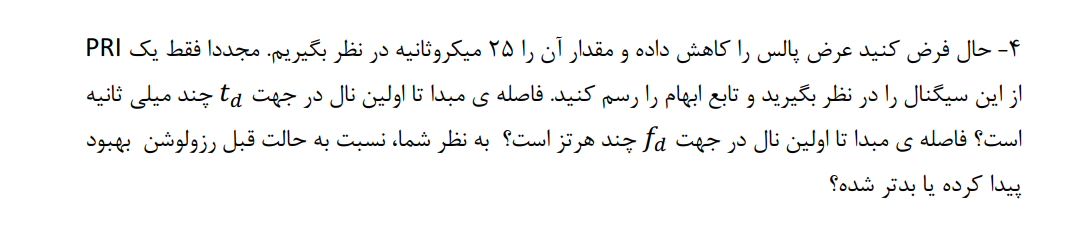

% Signals are considered to be in Low Frequency Band
ts =  1e-6; % --> to get 1 MHz --> 
fs=1/ts; % sampling rate --> 100Hz
C=300e6; % light speed

Tau_length = 25e-6;  % 25 muo s

tau_num=Tau_length/ts;  % --> Consider a single sample on the signal
tau=tau_num*ts; % --> the signal length would be equal to number of samples multiplied by length of each sample!

PRI=2.5e-3; % 2.5 ms
PRI_num=round(PRI/ts); % --> number of sqaured pulses in signal

PRF=1/PRI;

A=1;


Trecording=1 * PRI;   % --> Recording time at the receiver!

deltaf=1/Trecording; % Frequency Resolution

pulse_num=round(Trecording/PRI); % Number of pulse in recording time
sample_num=round(Trecording/ts);

t=0:ts:Trecording-ts; % Time Vector 
freq=-fs/2:deltaf:fs/2-deltaf; % Frequency Vector

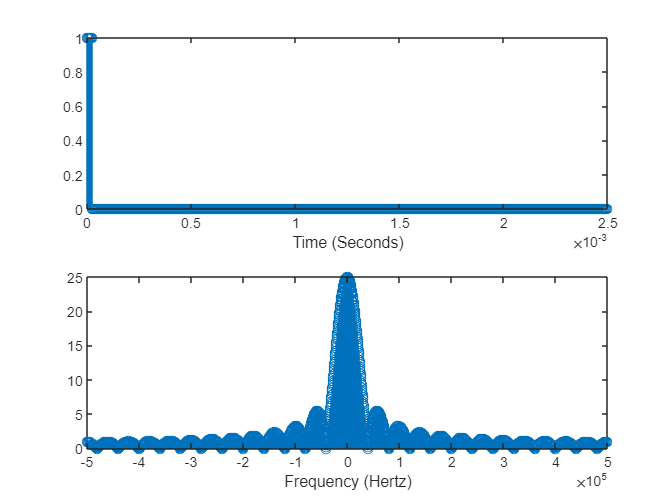

% Create Our Signal : The one Pulse:
SL2_PRI=A* [ones(1,floor(tau_num)) zeros(1,PRI_num-tau_num)]; % single pulse in the interval of sending and receiving
sl2=repmat(SL2_PRI,1,pulse_num); % Repeated pulse for each PRI in Trecording

figure(1)
subplot(2,1,1)
stem(t,sl2) % The Signal itself --> Pulse Train
xlabel('Time (Seconds)')
subplot(2,1,2)
slf2=fftshift(fft(sl2)); % shifted fft signal --> Fourier transformation --> I expect to see the sampled form of the expected Fourier transform with the distance of 1/PRI = PRF
stem(freq,abs(slf2)) % Frequency Domain
xlabel('Frequency (Hertz)')


% define td and fd vectors as mentioned in the first question:
delay_vector = -PRI : 1e-5 : PRI ;
doppler_freq_vector = -4e3: 1 : 4e3 ; % 8000Hz with 1Hz resolution

P = zeros(length(doppler_freq_vector),length(delay_vector));

for i=1:length(delay_vector)
    for j=1:length(doppler_freq_vector)
        td = delay_vector(i) ;
        fd = doppler_freq_vector(j);
        P(j,i) = sum(sl2.*conj(circshift(sl2,round(td/ts))) .* exp(-1j*2*pi*fd.*t)) ;  % sl(t)*sl(t-td)^ * exp(-1j*2*pi*fd*t) --> summation on t


    end
end


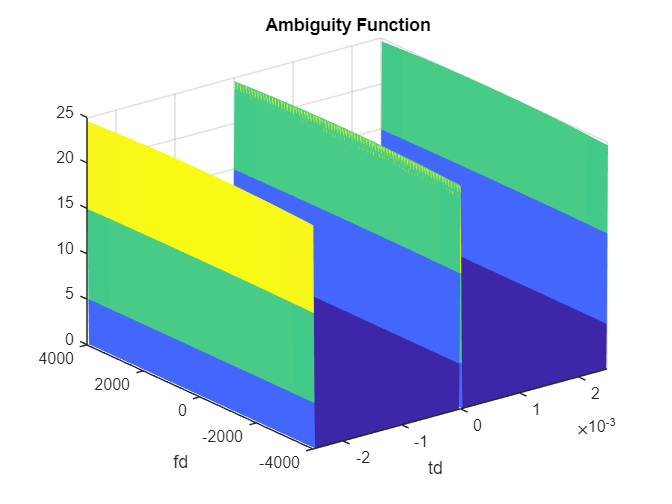


[TD,FD] = meshgrid(delay_vector , doppler_freq_vector) ; % Baze o motegharen greftam... Nemidunestam manzur ghesmate manfias ya mosbataro ham nesfe konam

figure()
h=surf(TD,FD,abs(P));
xlabel("td")
ylabel("fd")
title("Ambiguity Function")
set(h,'LineStyle','none')

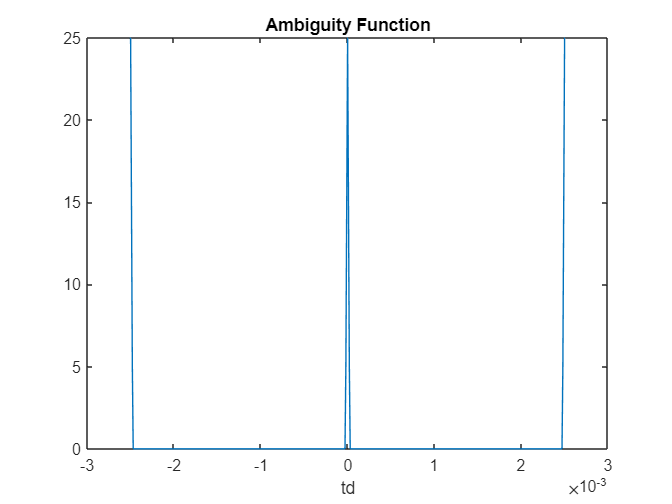


figure()
mid = floor(length(doppler_freq_vector)/2)+1; % the middle point
plot(delay_vector,abs( P(mid,:) ));
xlabel("td")
title("Ambiguity Function") 

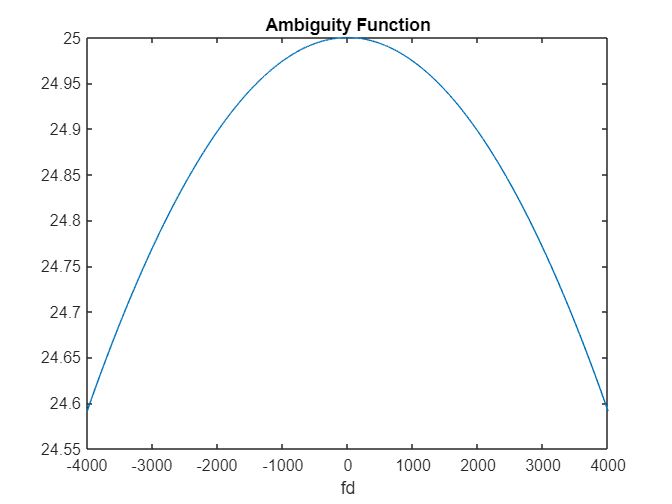

figure()
mid_t = floor(length(delay_vector)/2)+1; % the middle point
plot(doppler_freq_vector,abs( P(:,mid_t) ));
xlabel("fd")
title("Ambiguity Function") 

It is Obvious that in fd axis we have our nulls, further because 1/tau has been increased and it is now more than 4000 (actually 40000 Hz) because we divided tau to 10 then we expect to have our Ambiguity function in fd axis larger and in td axis narrower (close to delta form in time domain)!

frequency resolution is based on Trecord and that remains constant! --> also range resolution remains the same because it is proportional to 1/BW -->

resolutions have not been changed but the area where we can detect our target (its speed and its range is changed)!

Q5:

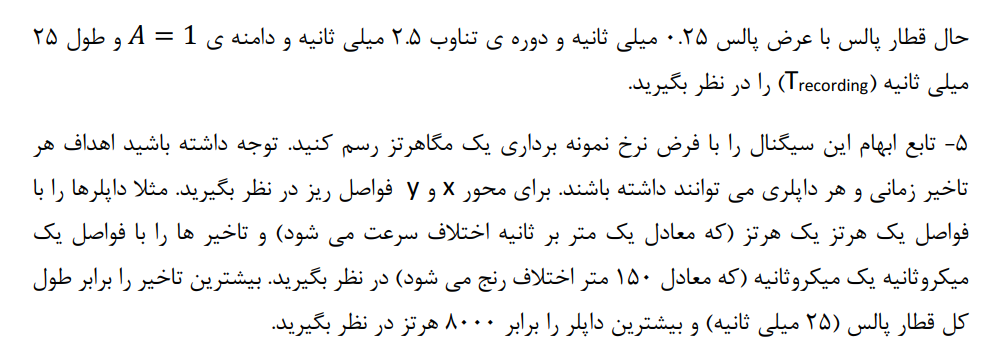

% Signals are considered to be in Low Frequency Band
ts =  1e-5; % --> to get 1 MHz --> 
fs=1/ts; % sampling rate --> 100Hz
C=300e6; % light speed

Tau_length = 0.25e-3;  % 0.25 ms

tau_num=Tau_length/ts;  % --> Consider a single sample on the signal
tau=tau_num*ts; % --> the signal length would be equal to number of samples multiplied by length of each sample!

PRI=2.5e-3; % 2.5 ms
PRI_num=round(PRI/ts); % --> number of sqaured pulses in signal

PRF=1/PRI;

A=1;


Trecording=10 * PRI;   % --> Recording time at the receiver!

deltaf=1/Trecording; % Frequency Resolution

pulse_num=round(Trecording/PRI); % Number of pulse in recording time
sample_num=round(Trecording/ts);

t=0:ts:Trecording-ts; % Time Vector 
freq=-fs/2:deltaf:fs/2-deltaf; % Frequency Vector

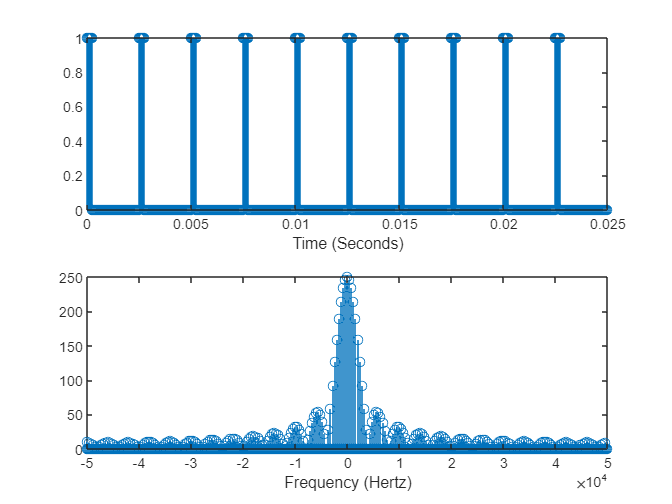

% Create Our Signal : The one Pulse:
SL3_PRI=A* [ones(1,floor(tau_num)) zeros(1,PRI_num-tau_num)]; % single pulse in the interval of sending and receiving
sl3=repmat(SL3_PRI,1,pulse_num); % Repeated pulse for each PRI in Trecording

figure(1)
subplot(2,1,1)
stem(t,sl3) % The Signal itself --> Pulse Train
xlabel('Time (Seconds)')
subplot(2,1,2)
slf3=fftshift(fft(sl3)); % shifted fft signal --> Fourier transformation --> I expect to see the sampled form of the expected Fourier transform with the distance of 1/PRI = PRF
stem(freq,abs(slf3)) % Frequency Domain
xlabel('Frequency (Hertz)')


% define td and fd vectors as mentioned in the first question:
delay_vector = -PRI : 1e-5 : PRI ;
doppler_freq_vector = -4e3: 1 : 4e3 ; % 8000Hz with 1Hz resolution

P3 = zeros(length(doppler_freq_vector),length(delay_vector));

for i=1:length(delay_vector)
    for j=1:length(doppler_freq_vector)
        td = delay_vector(i) ;
        fd = doppler_freq_vector(j);
        P3(j,i) = sum(sl3.*conj(circshift(sl3,round(td/ts))) .* exp(-1j*2*pi*fd.*t)) ;  % sl(t)*sl(t-td)^ * exp(-1j*2*pi*fd*t) --> summation on t


    end
end

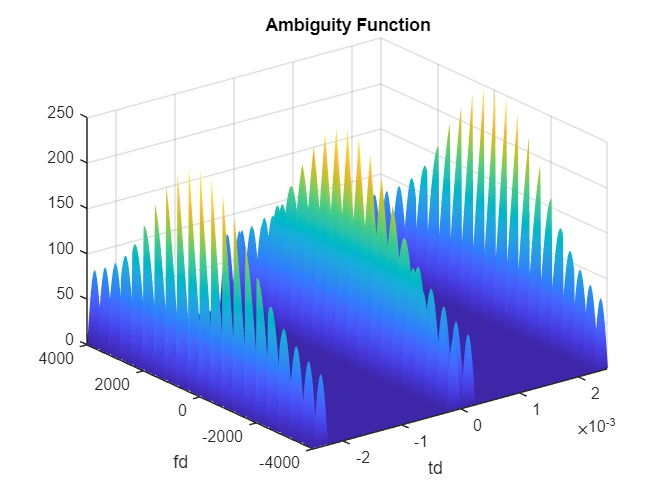


[TD,FD] = meshgrid(delay_vector , doppler_freq_vector) ; % Baze o motegharen greftam... Nemidunestam manzur ghesmate manfias ya mosbataro ham nesfe konam

figure()
h=surf(TD,FD,abs(P3));
xlabel("td")
ylabel("fd")
title("Ambiguity Function")
set(h,'LineStyle','none')

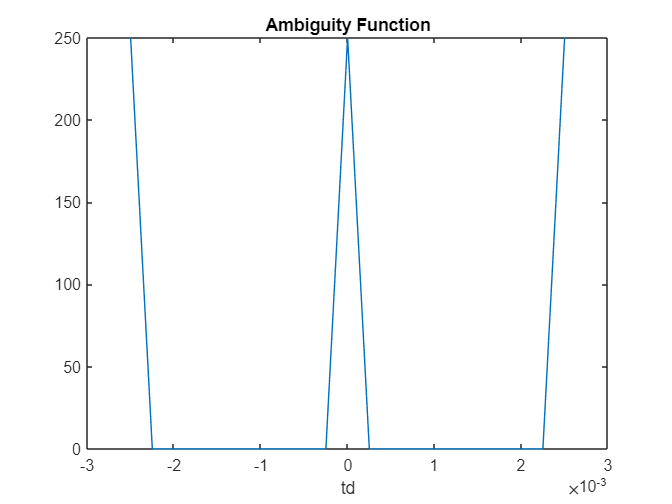


figure()
mid = floor(length(doppler_freq_vector)/2)+1; % the middle point
plot(delay_vector,abs( P3(mid,:) ));
xlabel("td")
title("Ambiguity Function") 

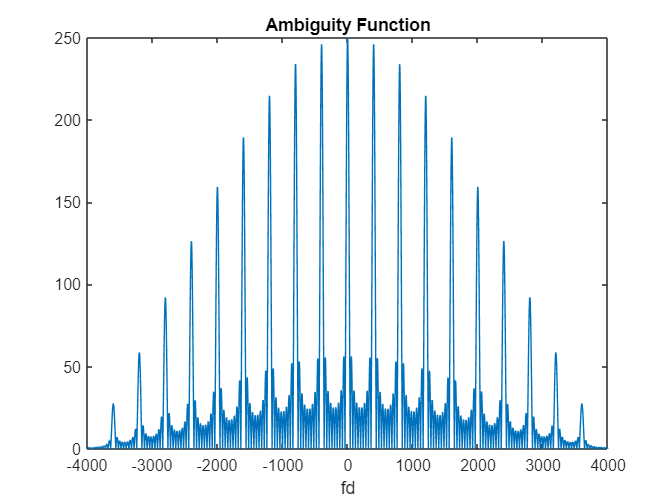



figure()
mid_t = floor(length(delay_vector)/2)+1; % the middle point
plot(doppler_freq_vector,abs( P3(:,mid_t) ));
xlabel("fd")
title("Ambiguity Function") 

### Q6:

we can see increasing Trecord results in better doppler frequency resolution! --> a better Sinc(f) is obtained!

the Nulls are steady at their place like they were before in the first configuration but the 1/Trecord is increased and so the doppler frequency!

To increase the resolution that is not increased (Range Resolution) we can get more **Bnadwidth**! --> use an Up-chirp signal

In General -->

$S_l \left(t\right)=\Pi \left(\frac{t}{T_{\mathrm{record}} }\right)*{\mathrm{rep}}_{\mathrm{PRI}} \left(\frac{t}{\tau }\right)$ ==> Fourier Transform --> $p\left(0,\mathrm{fd}\right)=F\left\lbrace {\left|S_l \left(t\right)\right|}^2 \right\rbrace \Rightarrow \;A\;=\;\mathrm{conv}\;\left(\;\;{\mathrm{comb}}_{\mathrm{PRF}\left(\right.} \left(\tau *\mathrm{sinc}\left(\tau f\right)\right)\;\;\;\;\;\;\;,\;\;\;\;T_{\mathrm{record}} *\mathrm{sinc}\left(T_{\mathrm{record}} \;f\right)\right)$ ==>

The $p\left(0,f_d \right)=\mathrm{conv}\left(A,A\right);$ --> 


$$p\left(t_d ,0\right)={\mathrm{rep}}_{\mathrm{PRI}} \left(\;\;\;\;\;\;\mathrm{conv}\left(\Pi \left(\frac{t}{\tau }\right),\Pi \left(\frac{t}{\tau }\right)\;\;\right)\;\;\;\;\;\right)-----\to \mathrm{conv}\left(\Lambda \left(\frac{t}{\tau }\right)\;,\;\Sigma \left(\delta \;\left(t-n*\mathrm{PRI}\right)\right)\right)\;=\Sigma \Lambda \left(\frac{\left(t-n*\mathrm{PRI}\right)}{\tau }\right)\;$$


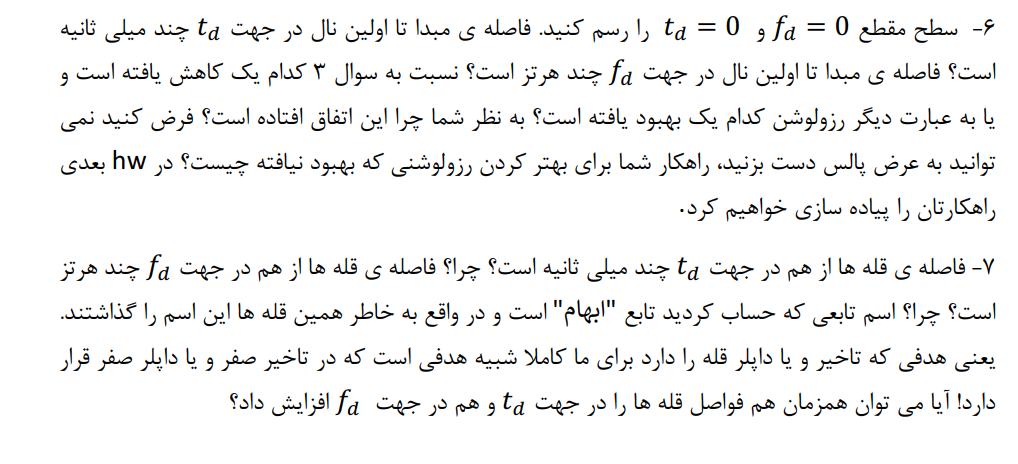

The Peaks distance is 2.5 ms because that is the PRI! 

The Peaks  in fd axis is400Hz --> we multiplied frequency resolution by 10 and kept the tau value constant so the nulls will be moved to 1/10 their previous position from 4000Hz to 400Hz! and they repeat every 400Hz

In Time domain, the signal is periodic and the peaks of that signal repeat every period (PRI).

In doppler axis, the peaks  repeat for every PRF!

Decreasing the PRI ==> Increase in PRF

Increase in PRI ==> Decrease in PRF

This means there is a trade-off here! --> A dilemma!

### Q7:

It represents the [distortion](https://en.wikipedia.org/wiki/Distortion) of a returned pulse due to the receiver [matched filter](https://en.wikipedia.org/wiki/Matched_filter)[[1]](https://en.wikipedia.org/wiki/Ambiguity_function#cite_note-1) (commonly, but not exclusively, used in [pulse compression](https://en.wikipedia.org/wiki/Pulse_compression) radar) of the return from a moving target. 

It represent how sure we are about the taregts sperated at a specific range and at a specific doppler distant!